%% Conjugate Gradient Method with checkpoints and plot (3 variables)
% Save this file as `conjugate_gradient_live_script_3var.m` and open it in MATLAB.
% The section breaks (%%) make it easy to run one step at a time.
clear; clc;
format compact;

%% Problem definition
% Change f, x0, or the symbols here to reuse the script on another problem.
syms x1 x2 x3 real
f = x1^2 + 2*x2^2 + 2*x3^2 + 2*(x1*x2) + 2*(x2*x3);

x0 = [2; 4; 10];

tolGrad = 1e-10;
maxSteps = 2;   % default: compute two steps (x1 and x2)

fprintf('Objective function f(x):\n');

Objective function f(x):


disp(f)

$${x_{1}}^{2}+2\,x_{1}\,x_{2}+2\,{x_{2}}^{2}+2\,x_{2}\,x_{3}+2\,{x_{3}}^{2}$$

fprintf('Initial point x0 = [%.6g, %.6g, %.6g]^T\n', x0(1), x0(2), x0(3));

Initial point x0 = [2, 4, 10]^T



%% Symbolic gradient
c = gradient(f, [x1, x2, x3]);

fprintf('\nSymbolic gradient c(x):\n');


Symbolic gradient c(x):


disp(c)

$$\left(\begin{array}{c} 2\,x_{1}+2\,x_{2}\\ 2\,x_{1}+4\,x_{2}+2\,x_{3}\\ 2\,x_{2}+4\,x_{3} \end{array}\right)$$


c0 = double(subs(c, [x1 x2 x3], x0.'));
f0 = double(subs(f, [x1 x2 x3], x0.'));

fprintf('Gradient at x0:\n');

Gradient at x0:


disp(c0)

    12
    40
    48


fprintf('Objective value at x0: %.12g\n', f0)

Objective value at x0: 332



%% Step 0: steepest descent direction
% Fletcher-Reeves conjugate gradient starts with d0 = -c0.
d0 = -c0;

fprintf('\nInitial search direction d0 = -c0:\n');


Initial search direction d0 = -c0:


disp(d0)

   -12
   -40
   -48



isDescent0 = (c0.' * d0) < 0;
fprintf('c(x0)^T d0 = %.12g\n', c0.' * d0);

c(x0)^T d0 = -4048


if isDescent0
    disp('This is a descent direction.');
else
    disp('This is NOT a descent direction.');
end

This is a descent direction.



%% Exact line search for step 0
syms alpha real
xAlpha0 = x0 + alpha*d0;
fAlpha0 = simplify(subs(f, [x1 x2 x3], xAlpha0.'));
dfAlpha0 = simplify(diff(fAlpha0, alpha));
alpha0Star = double(solve(dfAlpha0 == 0, alpha));

fprintf('\nLine search function f(alpha) for step 0:\n');


Line search function f(alpha) for step 0:


disp(fAlpha0)

$$12752\,\alpha^{2}-4048\,\alpha +332$$

fprintf('Derivative df/dalpha for step 0:\n');

Derivative df/dalpha for step 0:


disp(dfAlpha0)

$$25504\,\alpha -4048$$

fprintf('Candidate step size alpha0*:\n');

Candidate step size alpha0*:


disp(alpha0Star)

    0.1587



alpha0Star = alpha0Star(isreal(alpha0Star));
alpha0Star = alpha0Star(alpha0Star >= 0);
if isempty(alpha0Star)
    error('No nonnegative real step size found from the line search at step 0.');
end
alpha0Star = alpha0Star(1);

%% Update to x1
x1_new = x0 + alpha0Star * d0;

c1 = double(subs(c, [x1 x2 x3], x1_new.'));
f1 = double(subs(f, [x1 x2 x3], x1_new.'));



fprintf('\nNew iterate x1:\n');


New iterate x1:


disp(x1_new)

    0.0954
   -2.3488
    2.3814


fprintf('Gradient at x1:\n');

Gradient at x1:


disp(c1)

   -4.5069
   -4.4417
    4.8281


fprintf('Objective value at x1: %.12g\n', f1)

Objective value at x1: 10.7503136763



%% Fletcher-Reeves beta1 and conjugate direction d1
norm_c0 = norm(c0);
norm_c1 = norm(c1);
fprintf('|c0| and |c1|')

|c0| and |c1|

disp(norm_c0)

   63.6239


disp(norm_c1)

    7.9593





beta1 = (norm(c1) / norm(c0))^2;

fprintf('\nFletcher-Reeves beta1 = (||c1||/||c0||)^2:\n');


Fletcher-Reeves beta1 = (||c1||/||c0||)^2:


fprintf('beta1 = %.12g\n', beta1);

beta1 = 0.0156499671762



d1 = -c1 + beta1*d0;

fprintf('Conjugate direction d1 = -c1 + beta1*d0:\n');

Conjugate direction d1 = -c1 + beta1*d0:


disp(d1)

    4.3191
    3.8157
   -5.5793



isDescent1 = (c1.' * d1) < 0;
fprintf('c(x1)^T d1 = %.12g\n', c1.' * d1);

c(x1)^T d1 = -63.3510671291


if isDescent1
    disp('d1 is a descent direction.');
else
    disp('d1 is NOT a descent direction.');
end

d1 is a descent direction.



%% Exact line search for step 1
xAlpha1 = x1_new + alpha*d1;
fAlpha1 = simplify(subs(f, [x1 x2 x3], xAlpha1.'));
dfAlpha1 = simplify(diff(fAlpha1, alpha));
alpha1Star = double(solve(dfAlpha1 == 0, alpha));

fprintf('\nLine search function f(alpha) for step 1:\n');


Line search function f(alpha) for step 1:


disp(fAlpha1)

$$\frac{15911135184425398725806779727183\,\alpha^{2}}{158456325028528675187087900672}-\frac{222060888990150479\,\alpha }{3505243069349888}+\frac{8568}{797}$$

fprintf('Derivative df/dalpha for step 1:\n');

Derivative df/dalpha for step 1:


disp(dfAlpha1)

$$\frac{15911135184425398725806779727183\,\alpha }{79228162514264337593543950336}-\frac{222060888990150479}{3505243069349888}$$

fprintf('Candidate step size alpha1*:\n');

Candidate step size alpha1*:


disp(alpha1Star)

    0.3155



alpha1Star = alpha1Star(isreal(alpha1Star));
alpha1Star = alpha1Star(alpha1Star >= 0);
if isempty(alpha1Star)
    error('No nonnegative real step size found from the line search at step 1.');
end
alpha1Star = alpha1Star(1);

%% Update to x2
x2_new = x1_new + alpha1Star * d1;
c2 = double(subs(c, [x1 x2 x3], x2_new.'));
f2 = double(subs(f, [x1 x2 x3], x2_new.'));

fprintf('\nNew iterate x2:\n');


New iterate x2:


disp(x2_new)

    1.4578
   -1.1452
    0.6214


fprintf('Gradient at x2:\n');

Gradient at x2:


disp(c2)

    0.6253
   -0.4221
    0.1954


fprintf('Objective value at x2: %.12g\n', f2)

Objective value at x2: 0.758224711405


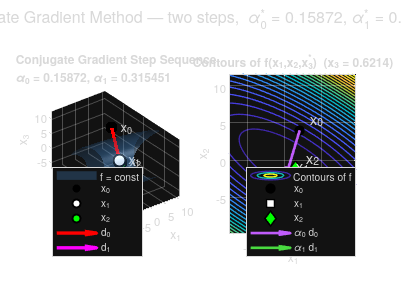


%% Plot: iterates and search directions
fHandle = matlabFunction(f, 'Vars', [x1, x2, x3]);

pts    = [x0, x1_new, x2_new];
xmid   = mean(pts, 2);
step1  = norm(x1_new - x0);
step2  = norm(x2_new - x1_new);
baseSpan = max([range(pts(1,:)), range(pts(2,:)), range(pts(3,:)), step1, step2, 1]);
pad    = 0.75 * baseSpan;

xRange = [min(pts(1,:))-pad,  max(pts(1,:))+pad];
yRange = [min(pts(2,:))-pad,  max(pts(2,:))+pad];
zRange = [min(pts(3,:))-pad,  max(pts(3,:))+pad];

nGrid = 60;
xv = linspace(xRange(1), xRange(2), nGrid);
yv = linspace(yRange(1), yRange(2), nGrid);
zv = linspace(zRange(1), zRange(2), nGrid);
[Xg, Yg, Zg] = meshgrid(xv, yv, zv);
Fg = fHandle(Xg, Yg, Zg);

fAt_x0 = f0;
fAt_x2 = f2;
isoLvl  = (fAt_x0 + fAt_x2) / 2;

figure('Color','w');

% --- subplot 1: 3-D isosurface + two step vectors ---
subplot(1,2,1);
hIso = isosurface(Xg, Yg, Zg, Fg, isoLvl);
p = patch(hIso);
p.FaceColor = [0.3 0.6 0.9];
p.EdgeColor = 'none';
p.FaceAlpha = 0.25;
hold on; grid on; axis equal;
view(3); lighting gouraud;
camlight('headlight');

scatter3(x0(1),     x0(2),     x0(3),     80, 'k', 'filled');
scatter3(x1_new(1), x1_new(2), x1_new(3), 80, 'w', 'filled', ...
         'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
scatter3(x2_new(1), x2_new(2), x2_new(3), 80, 'g', 'filled', ...
         'MarkerEdgeColor', 'k', 'LineWidth', 1.5);

stepVec0 = x1_new - x0;
stepVec1 = x2_new - x1_new;

quiver3(x0(1), x0(2), x0(3), stepVec0(1), stepVec0(2), stepVec0(3), 0, ...
        'r', 'LineWidth', 2.5, 'MaxHeadSize', 0.8);
quiver3(x1_new(1), x1_new(2), x1_new(3), stepVec1(1), stepVec1(2), stepVec1(3), 0, ...
        'm', 'LineWidth', 2.5, 'MaxHeadSize', 0.8);

text(x0(1),     x0(2),     x0(3),     '  x_0', 'FontSize', 10);
text(x1_new(1), x1_new(2), x1_new(3), '  x_1', 'FontSize', 10);
text(x2_new(1), x2_new(2), x2_new(3), '  x_2', 'FontSize', 10);

xlabel('x_1'); ylabel('x_2'); zlabel('x_3');
title(sprintf('Conjugate Gradient Step Sequence\\newline\\alpha_0 = %.6g, \\alpha_1 = %.6g', alpha0Star, alpha1Star));
legend('f = const', 'x_0', 'x_1', 'x_2', 'd_0', 'd_1', 'Location', 'best');

% --- subplot 2: 2-D contour slice at x3 = x2_new(3) ---
subplot(1,2,2);
x3_slice = x2_new(3);
nGrid2 = 250;
xv2 = linspace(xRange(1), xRange(2), nGrid2);
yv2 = linspace(yRange(1), yRange(2), nGrid2);
[Xg2, Yg2] = meshgrid(xv2, yv2);
Zg2 = fHandle(Xg2, Yg2, x3_slice);

contour(Xg2, Yg2, Zg2, 25, 'LineWidth', 1);
hold on; grid on; axis equal;
xlim(xRange); ylim(yRange);

plot(x0(1),     x0(2),     'ko', 'MarkerFaceColor', 'k',  'MarkerSize', 7);
plot(x1_new(1), x1_new(2), 'ks', 'MarkerFaceColor', 'w',  'MarkerSize', 8, ...
     'LineWidth', 1.5);
plot(x2_new(1), x2_new(2), 'kd', 'MarkerFaceColor', 'g',  'MarkerSize', 8, ...
     'LineWidth', 1.5);

quiver(x0(1), x0(2), stepVec0(1), stepVec0(2), 0, ...
       'LineWidth', 2, 'MaxHeadSize', 0.7);
quiver(x1_new(1), x1_new(2), stepVec1(1), stepVec1(2), 0, ...
       'LineWidth', 2, 'MaxHeadSize', 0.7);

text(x0(1),     x0(2),     '  x_0', 'FontSize', 11, 'VerticalAlignment', 'bottom');
text(x1_new(1), x1_new(2), '  x_1', 'FontSize', 11, 'VerticalAlignment', 'bottom');
text(x2_new(1), x2_new(2), '  x_2', 'FontSize', 11, 'VerticalAlignment', 'bottom');

title(sprintf('Contours of f(x_1,x_2,x_3^*)  (x_3 = %.4g)', x3_slice));
xlabel('x_1'); ylabel('x_2');
legend('Contours of f', 'x_0', 'x_1', 'x_2', '\alpha_0 d_0', '\alpha_1 d_1', 'Location', 'best');

sgtitle(sprintf('Conjugate Gradient Method — two steps,  \\alpha_0^* = %.6g, \\alpha_1^* = %.6g', alpha0Star, alpha1Star));


%% Summary for these two steps
fprintf('\nSummary of conjugate gradient steps:\n');


Summary of conjugate gradient steps:


fprintf('x0 = [%.6g, %.6g, %.6g]^T\n', x0(1), x0(2), x0(3));

x0 = [2, 4, 10]^T


fprintf('d0 = [%.6g, %.6g, %.6g]^T\n', d0(1), d0(2), d0(3));

d0 = [-12, -40, -48]^T


fprintf('alpha0* = %.12g\n', alpha0Star);

alpha0* = 0.158720200753


fprintf('x1 = [%.6g, %.6g, %.6g]^T\n', x1_new(1), x1_new(2), x1_new(3));

x1 = [0.0953576, -2.34881, 2.38143]^T


fprintf('beta1 = %.12g\n', beta1);

beta1 = 0.0156499671762


fprintf('d1 = [%.6g, %.6g, %.6g]^T\n', d1(1), d1(2), d1(3));

d1 = [4.3191, 3.81566, -5.5793]^T


fprintf('alpha1* = %.12g\n', alpha1Star);

alpha1* = 0.315451322849


fprintf('x2 = [%.6g, %.6g, %.6g]^T\n', x2_new(1), x2_new(2), x2_new(3));

x2 = [1.45782, -1.14515, 0.621432]^T


fprintf('||grad f(x2)||_2 = %.12g\n', norm(c2, 2));

||grad f(x2)||_2 = 0.779365607744



if norm(c2, 2) < tolGrad
    disp('Convergence criterion satisfied after two steps.');
else
    disp('Convergence criterion not yet satisfied after two steps.');
end

Convergence criterion not yet satisfied after two steps.
